clear

img = imread('../images/cavendish.jpg');
size(img)

ans =    600   800     3


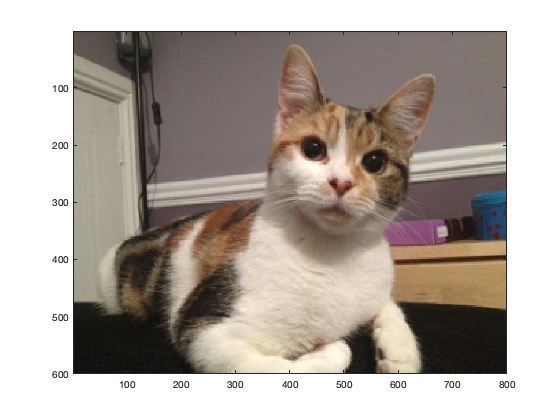

image(img)
exportgraphics(gcf,'cavendish_plot.png','Resolution',300) 

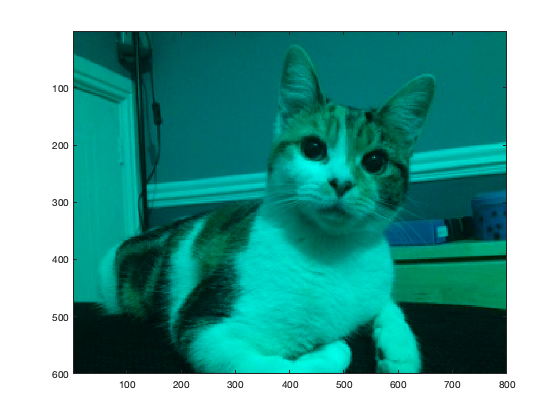

figure()

img_nored = img;
img_nored(:, :, 1) = 0;
image(img_nored)

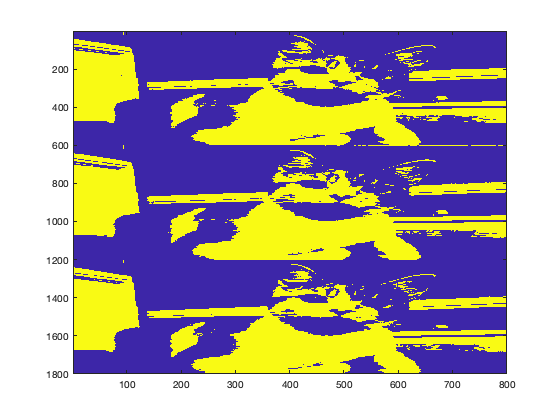


red = img(:, :, 1);
green = img(:, :, 2);
blue = img(:, :, 3);
avg_colour = mean(img, 3);
img_bw = [];
for i = 1 : 3
    colour = img(:, :, i);
    colour(avg_colour < 128) = 0;
    colour(avg_colour >= 128) = 255;
    img_bw = [img_bw ; colour];
end


image(img_bw)